# Set up and solve the associated differential equation: $$$RC\frac{dV_{in}}{dt} + V_{in} = sin(\omega t)$$ $$V_{in}(0) = 0$$ $$ \omega = (10)(2)\pi$$ $$ RC = 0.002$$$

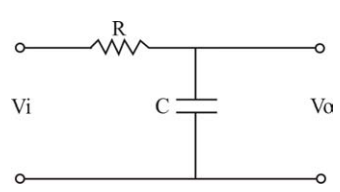

syms V_in(t) % create symbolic variable
omega = 10 * 2 * pi; % conversion from 10Hz to rad / sec
RC = 0.002; % time constant
ode = RC*diff(V_in,t) + V_in == sin(omega * t); % differential equation setup
cond = V_in(0) == 0; % initial condition

% symbolically solve the differential equation
V_out(t) = dsolve(ode,cond)

$$V\_out(t) = \frac{500\,\left(500\,\sin\left(20\,\pi \,t\right)-20\,\pi \,\cos\left(20\,\pi \,t\right)\right)}{400\,\pi^{2}+250000}+\frac{25\,\pi \,{\mathrm{e}}^{-500\,t}}{\pi^{2}+625}$$

# Create time interval and evaluate $$V_{in}(t)$$ and $$V_{out}(t)$ at the specified times for plotting

t = linspace(0,0.1,10000); %create time interval

y2 = sin(omega * t); % evaluate input voltage, V_in, at the time values
ys = matlabFunction(V_out); % convert symbolic function for V_out to a MATLAB function for time evaluation
ys1 = ys(t); %evaluate solution, V_out, at the time values

# Plot $$V_{in}(t)$$ and $$V_{out}(t)$$ on the same plot

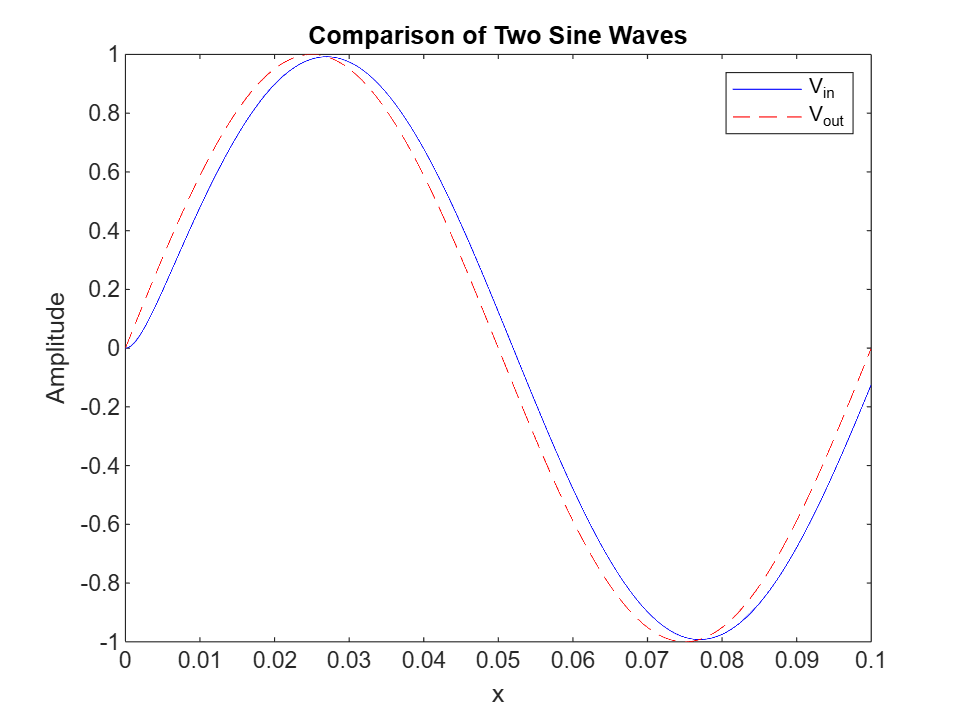

% Create the plot
figure;           % Open a new figure window
plot(t, ys1, 'b-', 'DisplayName', 'V_{in}'); % Plot the first sine wave in blue
hold on;         % Hold the current plot
plot(t, y2, 'r--', 'DisplayName', 'V_{out}'); % Plot the second sine wave in red dashed line

% Add labels and title
xlabel('x');
ylabel('Amplitude');
title('Comparison of Two Sine Waves');
legend show;     % Show legend
hold off;        % Release the hold on the current plot

# Create transfer function corresponding to the original differential equation: $$$H(s) =  \frac{V_{out}(s)}{V_{in}(s)}$$$, and Bode plot

% transfer function
H = tf([1],[omega * RC 1])


H =
 
       1
  ------------
  0.1257 s + 1
 
Continuous-time transfer function.
Model Properties


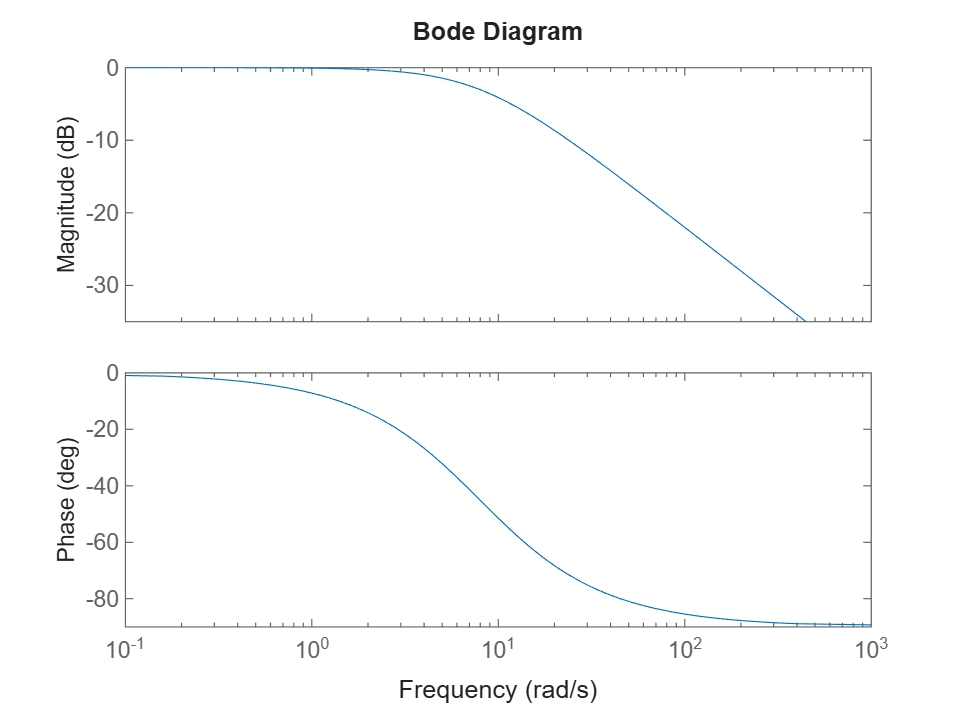

%Bode plot for H(s)
bode(H)